# 2021年度 ライフ実践プロジェクト day3

#### 担当　M2　桐原佑司

## Step0 はじめに

今回はこのmatlabの「ライブスクリプト」という機能を使って説明していきます．

ライブスクリプトを使った理由は3つです．

## **1．画像が張れる**

ここにカーソルを合わせクリックすると横のココが青くなるはずです．

ココ→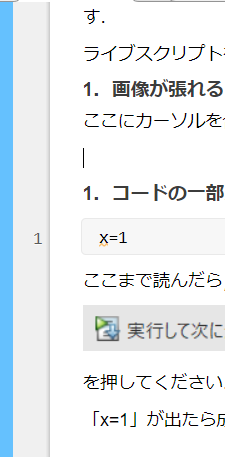

今後**このセクションを選択**と書いてあった場合，その指示が書いてある場所が青くなるようにしてください．

こんな感じで画像があると説明が楽なんです．

なので，画像使って各部の説明をしていきます．

名前は結構自分が普段読んでる適当な呼び方なんで，間違ってたらごめんなさい．

あとこれを入力しながら各部分の画像は撮っているので，細かいとこ違うと思います．

一応matlabのバージョンは2021aです．

#### ・スクリプトウインドウ

今これを読んでいる部分

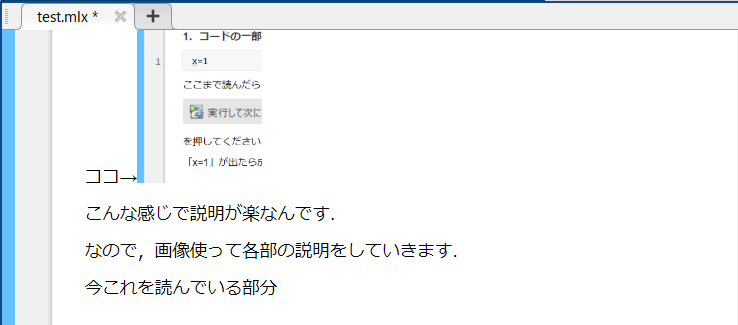

ここがコードを編集する部分です．画像上のリボンで複数開いたりできます

.mファイルや.mlxファイルはここで開きます．

#### ・コマンドウインドウ

下の

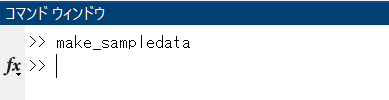

ここにエラーメッセージが出ます．

#### ・フォルダビュー

左の

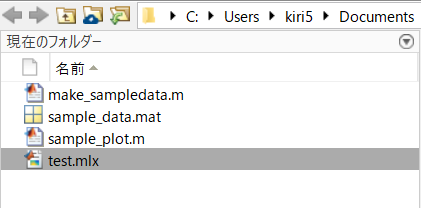

ここに今自分が開いてるフォルダの様子が表示されるはずです．

#### ・出力部

すぐ右の部分です

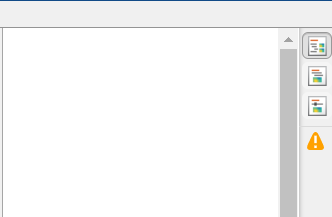

画像右上のなんか書類みたいな一番上の「右側に出力」にするとこのスペースが出てきます

関数の結果とかグラフが出てきます．

#### ・ワークスペース

一番右の部分です

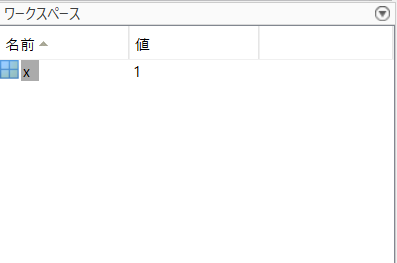

ここに変数が入ります．

今まで説明した

**・スクリプトウインドウ**

**・コマンドウインドウ**

**・フォルダビュー**

**・出力**

**・ワークスペース**

は境界にカーソル合わせると大きさ調整できるのでいい感じにしてください

ではライブスクリプトのいいとこの説明に戻ります

## **2．コードの一部だけを実行できること**

x=1

x = 1

ここまで読んだら，**このセクションを選択して**，

上のライブ エディタータブ，セクションの項の

を押してください．右のワークスペースと出力に

「x=1」が出たら成功です．（ワークスペースは前の画像のような感じ）

次にこのセクションを選択して同じようにしてください

clearvars

ワークスペースからxが消えたはずです．

こんな感じで**コードの一部だけ実行できるのでどこで間違えたかが一目瞭然**なんです．

次にコードの説明をします

%ここの灰色のボックスは関数を実行するためのコード部分です．ここに余計なこと書くとエラーが出ます．
%コード部分にメモしたいときはこのように先頭に「%」を付けると「コメントアウト」と呼ばれる
% 「見えるけど関数としては実行されない部分」になります．
%試しに改行して「x=1;」と書いてみて，実行してみてください

ワークスペースにxが出来たと思います．でも今回は出力に「x=1」が出ませんね？

コードの文末に「;」を付けると出力はされません．

膨大な計算するときは出力する時間が馬鹿にならないので**セミコロンを付けましょう**

では最後のライブスクリプトのいいとこです

## 3．変数を変えながら結果を見れる

ライブスクリプトは変数をリアルタイムで変えて出力できます

a=10

a = 10

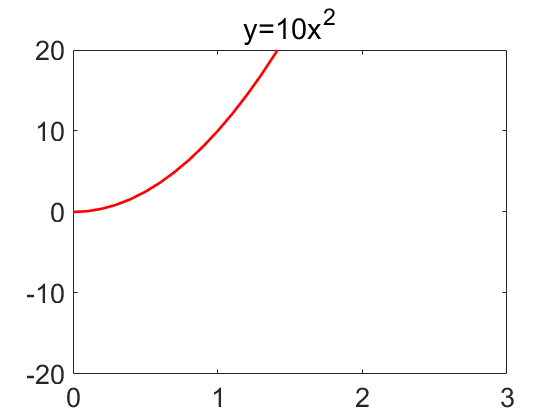

x=0:0.1:20;
y=a*x.^2;

plot(x,y,'LineWidth',2,"Color",[(10+a)/20 0 (10-a)/20])
xlim([0 3]);
ylim([-20 20]);
t=title(['y=',num2str(a),'x^2']);
t.FontSize=20;
set(gca,'FontSize',20,'FontName','Arial');

上のコードを実行して一行目のスライダをいじってみてください

グラフが動くと思います．こんな感じでできるのがいいとこです．

では**本番，データの編集に入りましょう．**

## Step0 関数の初期化，グラフの初期化

clearvars
close all

ここはそのまま実行するだけでいいです．

変数初期化のclearvarsとグラフウインドウ初期化のclose allです

## Step1 データのインポート

### 1-1 MATファイル作製

右のワークスペースで右クリックして「新規」を押してください．

「unnamed」という空の変数が追加されるはずです．ここではoutputと名付けましょう．

名前の所を二回クリックか右クリックで名前を変えられます．

outputをダブルクリックすると，このような画面が出るはずです．

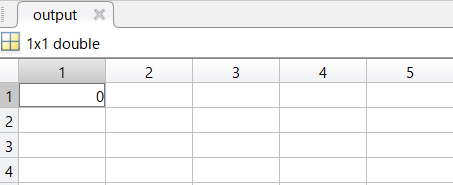

Excelの表みたいですね，ここに計測したExcelのデータを貼り付けてしまいましょう．

終わったらワークスペースで右クリックして「保存」を選んで**この.mlxファイルと同じ場所**に好きな名前で保存してください．他の.mファイルや.mlxファイルと異なり，半角英数から成る名前なら何でもいいです．

今後はこのデータを読み込んで解析を行います．

Excelから直接読み込むこともできますがデータサイズが大きいと時間がかかります．

なのでこのように使うデータ・変数はまとめて保存しておくと後で条件変えて計測するとき楽です．

## 1-2 データのインポート

を下に入力してください

path\filenameは自分のモノに合わせてください

%後で消す
load("sample_data.mat");

## Step2 まずはグラフをプロットしてみる

### 2-1 figureウインドウ作製

コードの先頭のfigure()はグラフ描画用のウインドウを開きます．

オプションのNameで名前を設定できます．

Fig1=figure('Name',"Step2");

### 2-2 plot関数

plot関数でoutputのグラフを書きましょう

説明で使用したplotはこのような形です．

plot関数はxを省略するとデータ行（列）を軸に取ります．

オプションの線の太さや色はお好みで，調べてもらえれば線を点線にしたりもできます．

plot関数以外で様々なグラフが書けます．[こちら](https://jp.mathworks.com/help/matlab/creating_plots/types-of-matlab-plots.html)

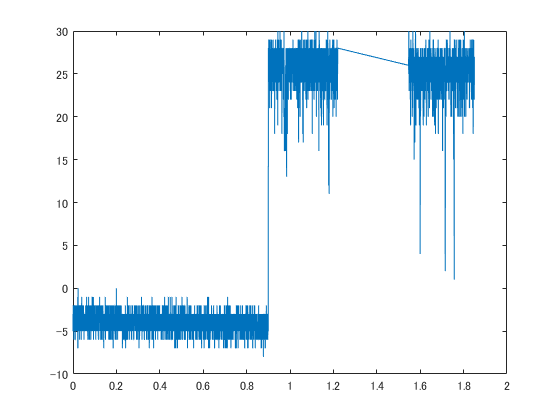

%後で消す
plot(time-time(1),output);

### 2-3 軸の範囲調整

今回自動で調整してくれるのであまり必要ありませんが，

複数のグラフを並べる時に自動で合わせられて軸が合っていないと見ずらいです．

なので軸の範囲の指定をしましょう．

説明での軸範囲の指定はこちらです   

xはあまりいじる意味ありませんがyは好きな様にしてください

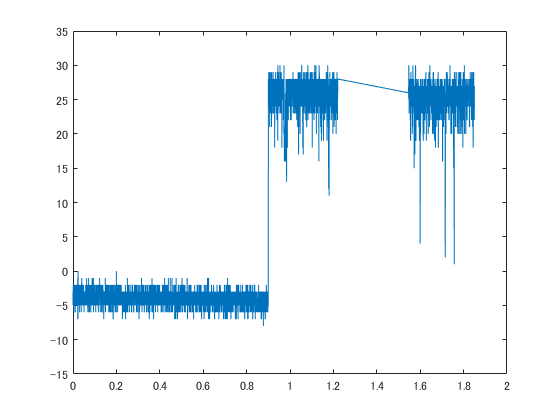

%後で消す
ylim([-15 35]);

### 2-4 タイトル，軸の大きさ調整

論文とかだとタイトルは挿入時に番号振るので，

ここで付ける必要はないです．

でも一応やっとくと

このように

の形でできます．

フォントサイズは

の様にして調整しましょう

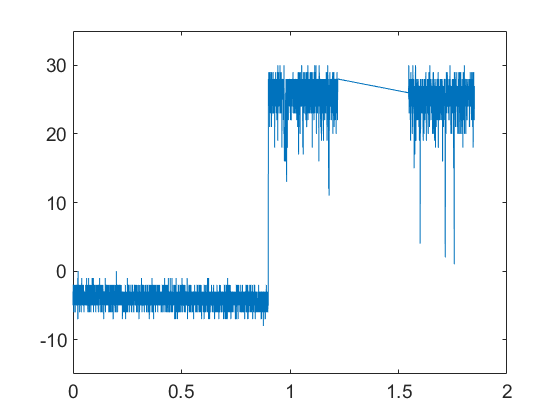

%後で消す
set(gca,'FontSize',14,'FontName','Arial');

### 2-5 見出しの作製

のような形で，nameとsizeを変えると内容と大きさを変えられます

legend("data",'Location','NorthWest',"FontSize",20);
xlabel('Time [s]');
ylabel('Electric current [pA]')
saveas(Fig1,"Fig1_step2.png");

## Step3 データを加工していく

### **目標**

目標は

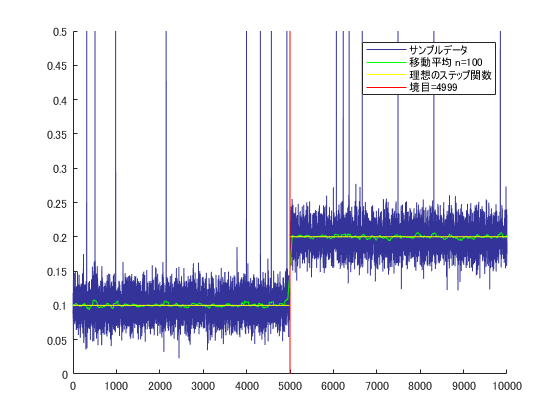

このグラフの様にデータを分割してそれぞれのグループで平均やヒストグラムを作ることです．

#### 3-1 移動平均を行う

データがこのままだとノイズが激しいのでその処理を行います．

ここで移動平均という処理をします．コロナ関係で聞いたことある人いるかもしれません

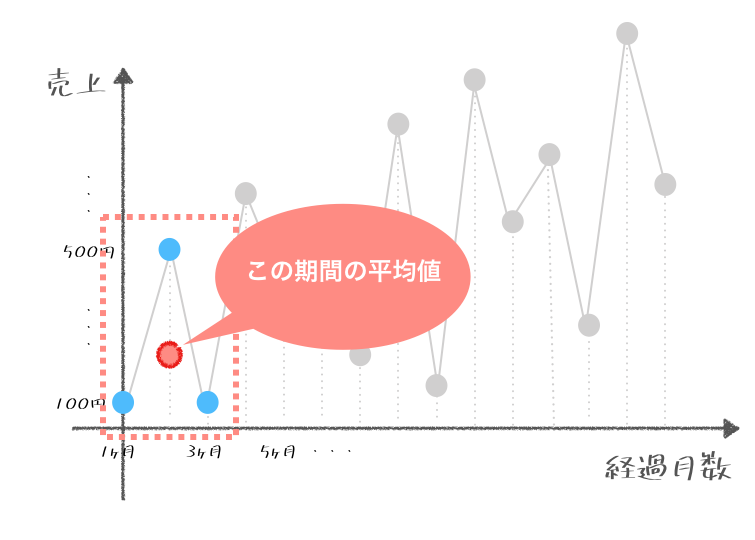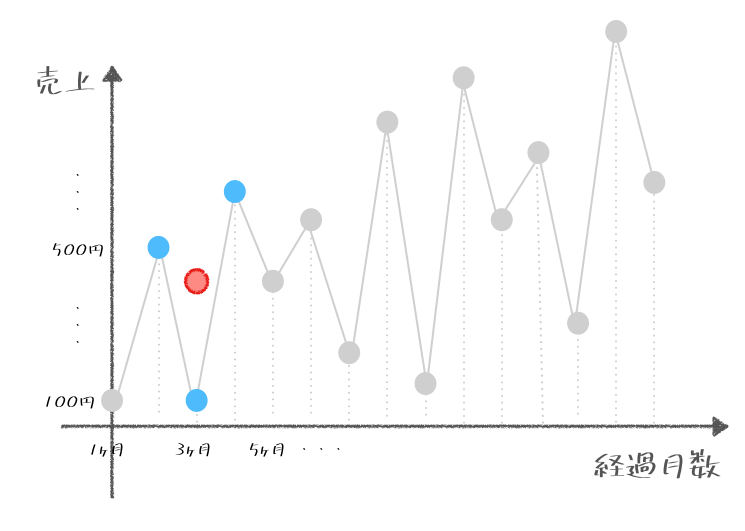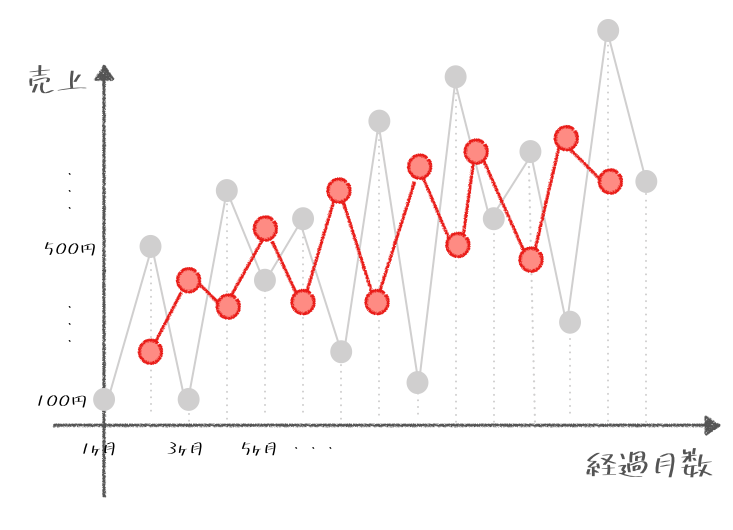

このように移動平均を行うとグラフを平滑化出来ます．

一方，あまりに大きく平均を取りすぎるとグラフはなだらかになって，

ステップ応答のようなものの応答がつぶれてしまいます．

移動平均を行う関数は以下の通りです

xに変数，nが平均の範囲(整数)です．

上の図ではn個の平均を取れない端の方は計算せず，nが大きくなるほど変数のサイズが小さくなっていますが，matlabの場合は計算できる範囲で計算するので

試しにnの値を色々変えてみましょう

%後で変数名を色々変える
range=100

range = 100

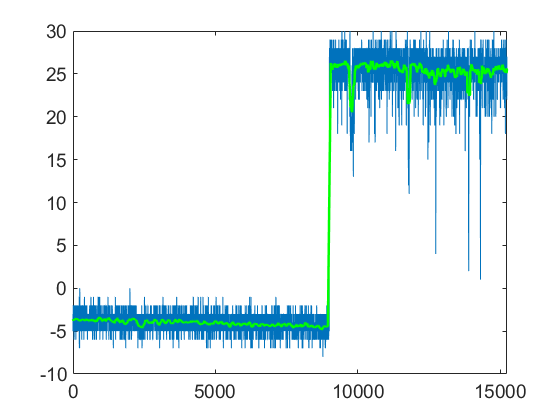

output2=movmean(output,range);
Fig2=figure('Name','Step3');
plot(output)
hold on
plot(output2,"-g","LineWidth",2)
ylim([-10 30]);
set(gca,'FontSize',14,'FontName','Arial');
saveas(Fig2,"Fig2_step3-1.png");


l=numel(output);

おそらくデータ数の1/100位が丁度いいはずです．

後で使うのでこの値を最後にlとして置いちゃってます．

このノイズ処理は画像に対しても行われ，meanフィルターと呼ばれています(重み付け等少し違うとこはありますが）

### 3-2 境界を探す

はここから境界を探すにはどうしたらいいでしょうか？

fig2を見てもらうと，境目で値が急変化していることが分かります．

この値を基準に境目を作れそうです．

output2の傾きをとってみましょう．

ここでプログラムの書き方の基本となる**三つの要素**について説明します

①順序…どの順番で処理を行うかの流れです．matlabでは基本上から下へ流れます

②条件分岐…Aの場合はこう，Bの場合はこうといった処理の分岐です．

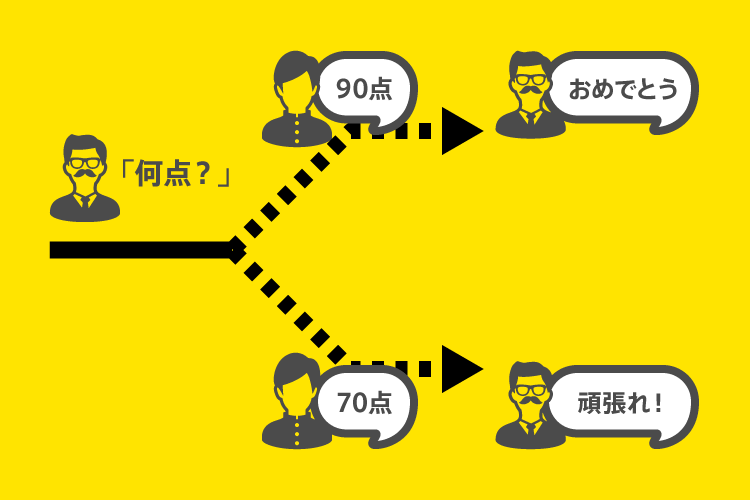

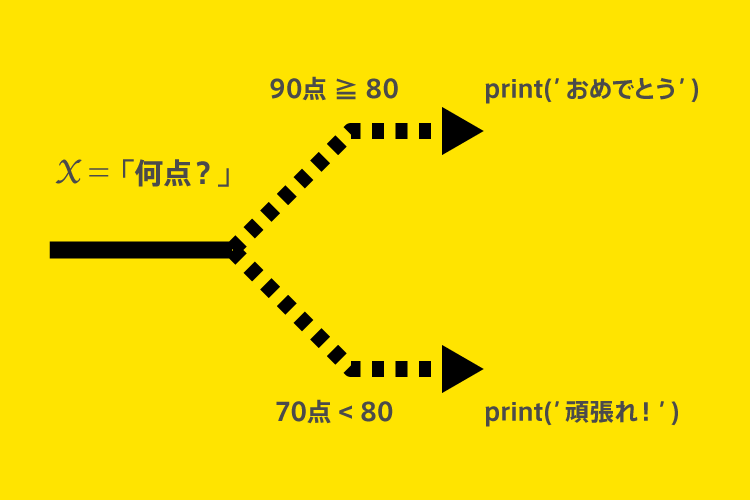

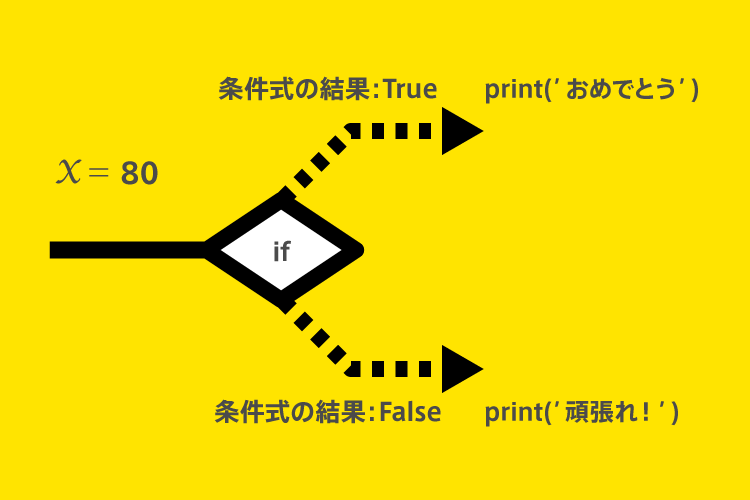

              条件式が正しい時に中のコードを実行します．

　　　　　　matlabでは

*                    と書きます*

③反復…    同じことを何回も繰り返して行う処理です．

                  代表的なものに「for文」と「while文」があります．

                  for文は指定した回数（i=0~n）同じことを繰り返し

　　　　　while文は指定条件を満たすまで同じことをします．

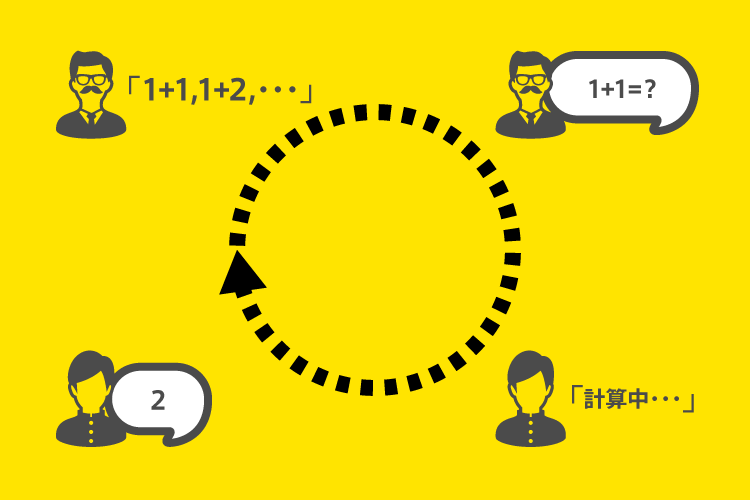

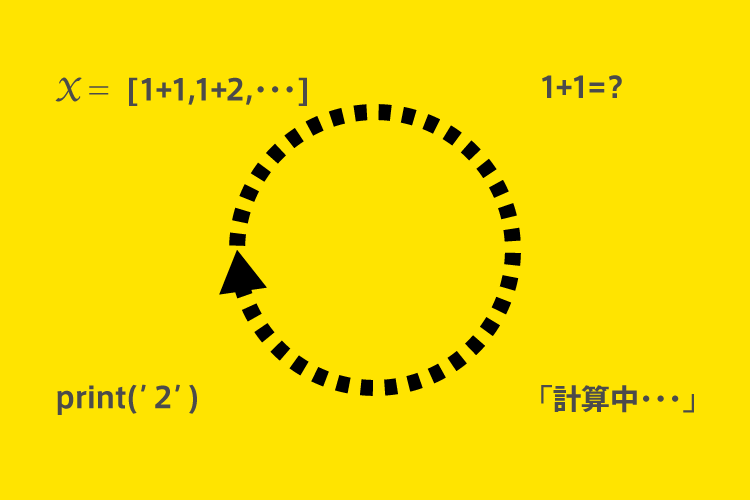

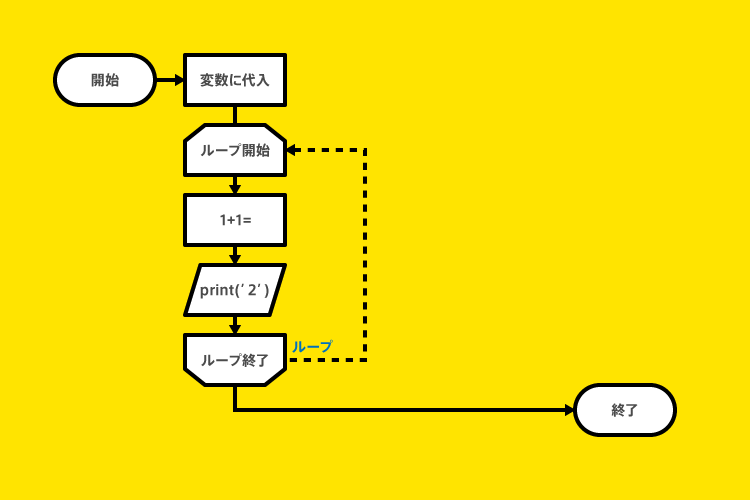

　　　　    matlabでは

*                    と書きます．他にもwhile文などがありますが今回は使いません*

**ほとんどのプログラムはこの組み合わせ**です．

そしてもう一つ，値を格納する「**配列**」という概念があります．

プログラムにおける「配列」とは、情報を記憶しておくための箱である変数の一つで、複数の箱が連なっているものの事を言います．

もう少し簡単に言うと、複数のデータをまとめてひと固まりとしてみて，一つの変数として見たものです．

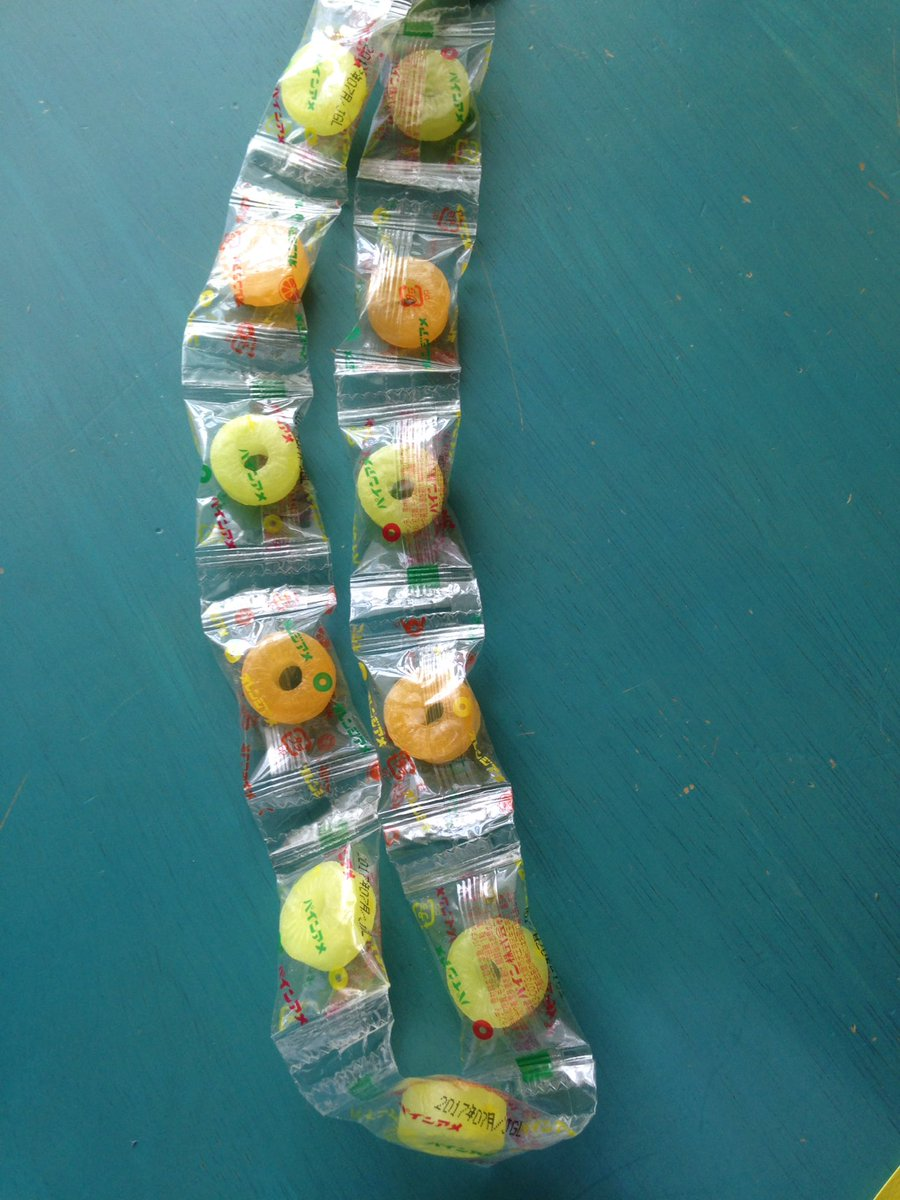

次の図のようなイメージになります．箱の上についた数字は添字で，箱の番号です．ほとんどのプログラム言語で0から始まりますが**なぜかmatlabでは1から始まります**．

この前から何番目かを表す数字を通常「**添字**」，中のデータを「**要素**」と言います．

これはmatlabの数字が一つずつ格納される配列は行列の一種として処理（計算）ができるので，その関係だと個人的には思ってます．

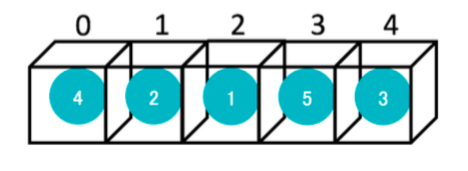

matlabでは配列の基本操作は以下のように行います．

「output2の傾きをとる」という操作をさっきの三つと配列を組み合わせて考えましょう

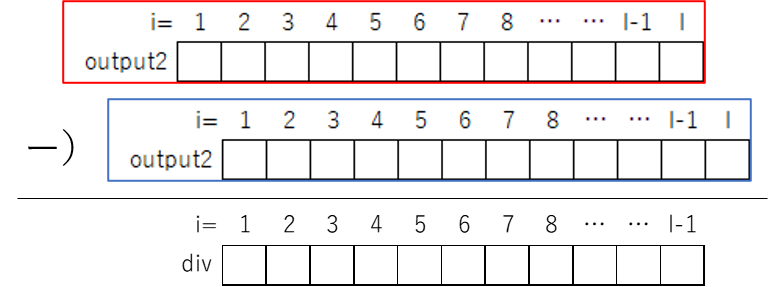

1. 差を格納するゼロ配列divを作製する

2. for文でl-1回，output2をずらして引き算する

3. divをプロット

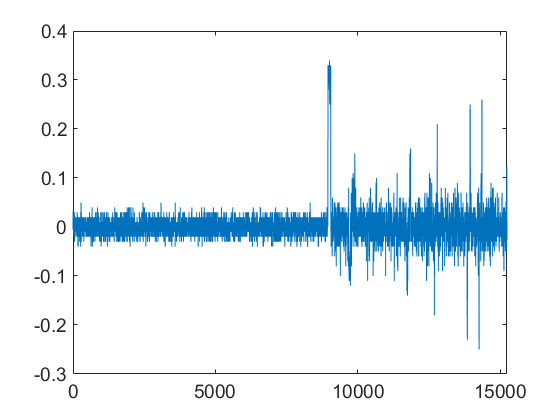

%　1をこの下に
div=zeros(1,l-1);
%　2をこの下に
for i=1:l-1
    div(1,i)=output2(i+1)-output2(i);
end
%ここから3
Fig3=figure("Name","Step3-2");
plot(div)
set(gca,'FontSize',14,'FontName','Arial');
saveas(Fig3,"Fig3_step3-2.png");

…やってみて分かると思いますがあんま平らになりませんね

でも境目のところあたりで線が上に来ています．

ここでもう一回移動平均を取りましょう

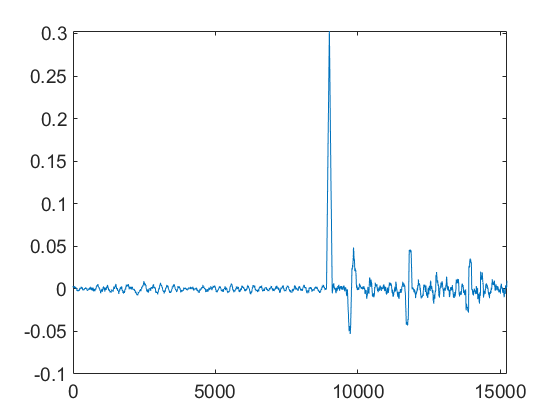

Fig4=figure("Name","Step3-2 take2");
div=movmean(div,range);
plot(div)
set(gca,'FontSize',14,'FontName','Arial');
saveas(Fig4,"Fig4_step3-2.png");

この最大値の列番号を同じく求めていきます

bound_num=find(div==max(div));

### 3－3 確認

このbound_numを使ってグラフを書いてしまいましょう

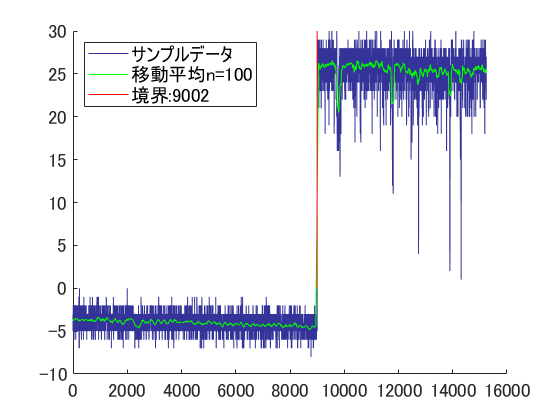

Fig5=figure('Name','Step3-3');
hold on
plot(output,'Color',[0.2 0.2 0.6]);
plot(output2,'Color','g');
line([bound_num bound_num],[0 max(output)],"Color",'r');
txt=['境界:',num2str(bound_num)];
legend(["サンプルデータ",['移動平均n=',num2str(range)],txt],'FontSize',14,"Location","northwest");
hold off
set(gca,'FontSize',14);
saveas(Fig5,"Fig5_step3-3.png");

ついでにデータをこの境界で分けてしまいます

output_div={output(1:bound_num-1),output(bound_num:l)};

この{}でくくった配列はcell配列と呼ばれ，サイズの違う配列（行列）や文字列を格納できます．またそれらの複合も格納できます．

上記はbound_numを基準にoutputを分けました

## Step4 データの解析

### 4-1　平均

いよいよ解析です．

前後の平均を取ります．

cellの配列の取り出し方は

平均値と標準誤差は

です．

前半の平均をave1, 後半の平均をave2で取りましょう

%===ここにoutput_divの前半の平均をave(1), 後半をave(2)でとる．標準誤差もそれぞれsd(1), sd(2)で===
%平均
ave=[mean(output_div{1}) mean(output_div{2})];

%標準誤差
sd=[std(output_div{1})/sqrt(numel(output_div{1})) std(output_div{2})/sqrt(numel(output_div{2}))];
%===================================================================================

次に棒グラフを書きます．棒グラフは

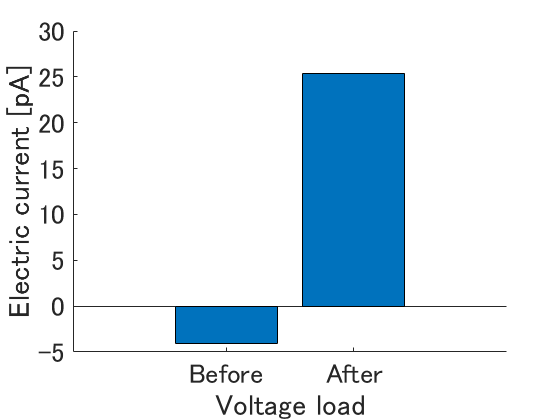

Fig6=figure("Name","Step4-1");
hold on
bar(ave);

xticks([1 2])
xticklabels({'Before','After'})
xlabel('Voltage load');
ylabel('Electric current [pA]');

set(gca,'FontSize',20);

標準誤差は

で書いてください．Colorのkはblackのkです．bにするとblue になります．

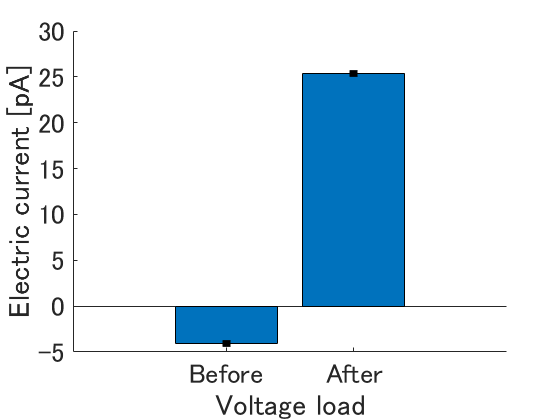

er=errorbar([1 2],ave,sd,'.',"LineWidth",5,"LineStyle","none","Color",'k');
saveas(Fig6,"Fig6_step4-1.png");

### 4-2 ヒストグラム

ヒストグラムは以下のように記述します

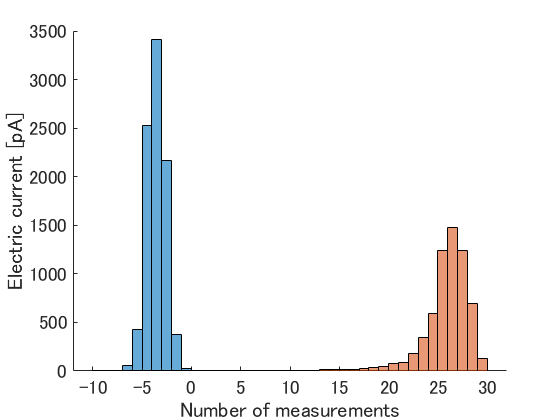

Fig7=figure("Name","Step4-2");
%このピン配置で書いてください
edges=-10:1:30;
%後で消す
hold on
h1=histogram(output_div{1},edges);
h2=histogram(output_div{2},edges);
%ここまで消す
xlabel('Number of measurements');
ylabel('Electric current [pA]');
N=max([histcounts(output_div{1},edges) histcounts(output_div{2},edges)]);
set(gca,'FontSize',14);
saveas(Fig7,"Fig7_step4-2.png");